# DSGE Replication code for Weather Shocks

Gallic, E. and Vermandel, G. (2020), "Weather Shocks", European Economic Review

**Context:** This live script reproduces key ts of the paper for the NGFS Macromodelling Workstream on climate-related macroeconomic risks. It provides a framework to simulate and visualize the macroeconomic  transmission of *weather shocks*—temporary fluctuations in temperature and precipitation—within a Dynamic Stochastic General Equilibrium (DSGE) environment calibrated for policy analysis.

## Load the Dynare Estimated Model

In this section, we will sequentially reproduce the main results of the paper.  We begin by **loading the estimated model** from the Dynare *.mod* file.

To execute this section only, click **Run Section** in the Live Editor toolbar  or press **Ctrl + Enter** on your keyboard.

This will initialize all parameters, steady states, and estimated shocks required for the subsequent simulations.

dynare RBC_q1.mod

Starting Dynare (version 6.3).
Calling Dynare with arguments: none
Starting preprocessing of the model file ... 
Substitution of endo lags >= 2: added 15 auxiliary variables and equations. 
Found 84 equation(s). 
Evaluating expressions... 
Computing static model derivatives (order 1). 
Normalizing the static model... 
Finding the optimal block decomposition of the static model... 
21 block(s) found: 
  20 recursive block(s) and 1 simultaneous block(s). 
  the largest simultaneous block has 32 equation(s) 
                                 and 32 feedback variable(s). 
Computing dynamic model derivatives (order 1). 
Normalizing the dynamic model... 
Finding the optimal block decomposition of the dynamic model... 
17 block(s) found: 
  16 recursive block(s) and 1 simultaneous block(s). 
  the largest simultaneous block has 36 equation(s) 
                                 and 32 feedback variable(s). 
terminate called after throwing an instance of 'std::filesystem::__cxx11::filesystem_erro

Error using dynare
Dynare: preprocessing failed

## Table 6: Steady-State Ratios

This section  reports the key steady-state ratios of the model economy. The computed values are based on the deterministic steady state obtained  from the Dynare solution (`oo_.dr.ys`). For each endogenous variable, its steady-state value is stored in a MATLAB variable ending with `_ss`.

for i1 = 1:M_.endo_nbr
	eval([deblank(M_.endo_names{i1}) '_ss = ' num2str(oo_.dr.ys(i1)) ';'])  ;
end
fprintf('\n\n\nTABLE 6: STEADY_STATE RATIOS\n\n')




TABLE 6: STEADY_STATE RATIOS



fprintf('%10s \t = %4.2f \t %4.2f \n','C/Y',c_ss/gdp_ss,0.57);

       C/Y 	 = 0.55 	 0.57 


fprintf('%10s \t = %4.2f \t %4.2f \n','i/y',i_ss/gdp_ss,0.22);

       i/y 	 = 0.23 	 0.22 


fprintf('%10s \t = %4.2f \t %4.2f \n','(r-1)*400',(r_ss-1)*400,4.75);

 (r-1)*400 	 = 4.72 	 4.75 


fprintf('%10s \t = %4.2f \t %4.2f \n','openess',(1-varphi)*alpha_N + varphi*alpha_A,0.29);

   openess 	 = 0.28 	 0.29 


fprintf('%10s \t = %4.2f \t %4.2f \n','nY^A/Y',n_ss*y_A_ss/gdp_ss,0.07);

    nY^A/Y 	 = 0.08 	 0.07 


fprintf('\n\n\n')


### Table 4:  Calibrated parameters on a quarterly basis

This script retrieves a selected list of calibrated parameter names from the Dynare model output and matches them to their entries in `M_.param_names`.

It then displays each parameter’s name, long description, and numerical value in a formatted table in the MATLAB console.

% 1) Choose the parameters to display (order as in the paper figure)
vname = {'beta', 'delta_K', 'alpha', 'gy', 'varphi', ...
         'Hss', 'Lss', 'alpha_N', 'alpha_A', 'chi_b'};


% 3) Pretty header
fprintf('\nTable 4: Calibrated parameters on a quarterly basis.\n');


Table 4: Calibrated parameters on a quarterly basis.


hdr1 = sprintf('%-14s %-40s %10s', 'Variable', 'Interpretation', 'Value');
fprintf('%s\n', hdr1);

Variable       Interpretation                                Value


fprintf('%s\n', repmat('-', 1, numel(hdr1)));

------------------------------------------------------------------



% 4) Loop over requested parameters, find their index in M_.param_names, and print
for i = 1:numel(vname)
    this = vname{i};
    % exact match
    id = find(strcmp(M_.param_names, this), 1, 'first');

    longtxt = M_.param_names_long{id};

    val = M_.params(id);
    fprintf('%-8s %-42s %10.4f\n', M_.param_names{id}, longtxt, val);
end

beta     discount factor                                0.9883
delta_K  capital depreciation rate                      0.0250
alpha    share of capital in output                     0.3300
gy       government spending to output ratio            0.2200
varphi   share of agricultural goods in consumption     0.1500
Hss      Steady state Hours                             0.3333
Lss      steady-state land supply                       0.4000
alpha_N  openness of non-agricultural market            0.2500
alpha_A  openness of agricultural market                0.4500
chi_b    portfolio adjustment cost                      0.0007


fprintf('\n');

### Table 7: Business Cycle Second-Moment Statistics

This section reproduces *Table 7* which compares the model-implied and empirical second-moment statistics of key macroeconomic variables affected by weather shocks. 

The model is simulated using *stoch_simul* to obtain  theoretical moments under the stationary solution. Empirical moments are  computed from the data contained in *dataset_*.

The script below reports, for each observable variable (output, consumption, investment, labor, real exchange rate, etc.), the model-implied moments versus their empirical counterparts:

var_list_ = {'y_obs','c_obs','h_obs','i_obs','y_a_obs','wy_obs','rer_obs','smdi_obs'};
options_.order = 1;
options_.irf = 0;
options_.noprint = 1;
[info, oo_, options_, M_] = stoch_simul(M_, options_, oo_, var_list_);

%%%%%%%%%%%% SHOW BUSINESS CYCLES MOMENTS
idym = strmatch('y_obs',var_list_,'exact');
idyd = strmatch('y_obs',dataset_.name,'exact');
thedatay = dataset_.data(options_.presample:end,idyd);
fprintf('\n\n')
fprintf('TABLE 7: BUSINESS CYCLES SECOND MOMENT STATISTICS \n')

TABLE 7: BUSINESS CYCLES SECOND MOMENT STATISTICS 


fprintf('%10s \t %12s \t\t %12s \t\t %12s \n',' ','Std Dev.','Autocorr.','Correl. GDP')

           	     Std Dev. 		    Autocorr. 		  Correl. GDP 


fprintf('%10s \t %5s vs %5s \t %s vs %5s \t %5s vs %5s \n','serie','Model','Data','Model','Data','Model','Data')

     serie 	 Model vs  Data 	 Model vs  Data 	 Model vs  Data 


for i=1:length(dataset_.name)
	thedata = dataset_.data(options_.presample:end,i);
	idx     = strmatch(dataset_.name{i},var_list_,'exact');
	thecorr1=corrcoef(thedata(2:end),thedata(1:end-1));
	thecorr2=corrcoef(thedata,thedatay);
	
		fprintf('%10s \t %2.2f  vs  %2.2f \t %2.2f  vs  %2.2f \t %2.2f  vs  %2.2f \n',...
		dataset_.name{i},...
		...% STD
		oo_.var(idx,idx)^0.5,...
		std(dataset_.data(options_.presample:end,i)),...
		...% AC
		oo_.autocorr{1}(idx,idx),...
		thecorr1(1,2),...
		...% CORRy
		oo_.var(idx,idym)/(sqrt(oo_.var(idx,idx))*sqrt(oo_.var(idym,idym))),...
		thecorr2(1,2)...
		)
end

  smdi_obs 	 1.08  vs  0.86 	 0.38  vs  0.37 	 -0.12  vs  -0.02 
   y_a_obs 	 14.72  vs  13.32 	 0.92  vs  0.92 	 0.60  vs  0.40 
    wy_obs 	 2.13  vs  3.45 	 0.95  vs  0.98 	 0.14  vs  0.65 
     y_obs 	 3.44  vs  2.72 	 0.91  vs  0.95 	 1.00  vs  1.00 
     h_obs 	 2.81  vs  2.80 	 0.85  vs  0.97 	 0.14  vs  0.05 
     c_obs 	 5.30  vs  2.50 	 0.94  vs  0.90 	 0.73  vs  0.72 
     i_obs 	 9.84  vs  11.94 	 0.88  vs  0.94 	 0.72  vs  0.68 
   rer_obs 	 3.37  vs  3.60 	 0.27  vs  0.26 	 0.03  vs  0.07 


fprintf('\n\n')

## Figure 6: Weather shocks realization

The script constructs a one-standard-deviation innovation to the weather disturbance (ηˢₜ), solves the model using Dynare’s resol function, and simulates the dynamic responses of key macro variables over time.

Each variable in the list yvar (output, consumption, investment, labor,  real exchange rate, and weather-related observables) is plotted as a percentage deviation from its steady state.

The resulting figure provides a compact visualization of how transitory  weather shocks propagate through production, demand, and the external balance in the model economy.

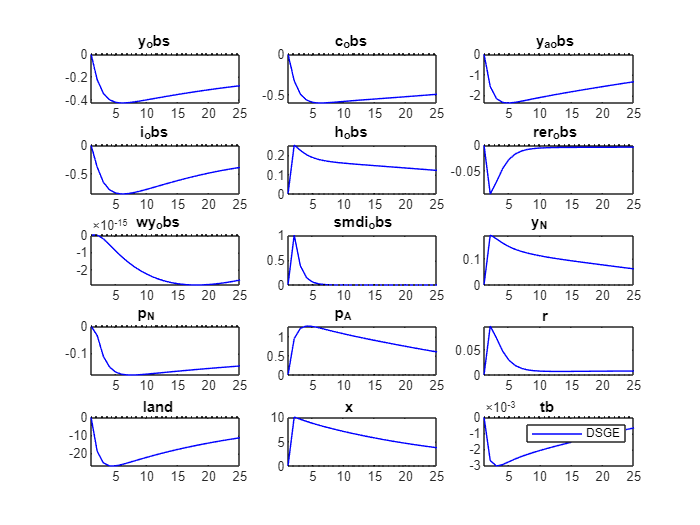

idx 			= strmatch('eta_s',M_.exo_names,'exact');

ee				= zeros(25,M_.exo_nbr);
ee(1,idx)		= 1;
[oo_.dr,~,M_.params] = resol(0, M_, options_, oo_.dr, oo_.dr.ys, oo_.exo_steady_state, oo_.exo_det_steady_state);
y0 = simult_(M_,options_,oo_.dr.ys,oo_.dr,ee,1)';
ss0          	= oo_.dr.ys;
yvar			= 	char('y_obs','c_obs','y_a_obs','i_obs','h_obs','rer_obs','wy_obs','smdi_obs','y_N','p_N','p_A','r','land','x','tb');
figure('NumberTitle', 'off', 'Name', 'Fig 7 Weather IRF');
T = 1:size(ee,1);
for i1 = 1:size(yvar,1)
	subplot(5,3,i1)
		idx = strmatch(deblank(yvar(i1,:)),M_.endo_names,'exact');
        if ss0(idx) ~= 0
			y0(:,idx) = (y0(:,idx)/ss0(idx)-1)*100;
        end
        plot(T,y0(T,idx),'b',T,zeros(size(T)),'k:')
        title(yvar(i1,:))
        xlim([min(T) max(T)])
        ylim([min(y0(T,idx)) max(y0(T,idx))])
end
legend('DSGE')

## Figure 7: Forecast error variance decomposition at the posterior mean

This section reproduces the decomposition of forecast error variances across main shock categories at different horizons.

The model is simulated using Dynare’s stoch_simul command at first order to compute the conditional variance decomposition for key observables: output, agricultural output, consumption, and hours worked.

Shocks are grouped into four categories:

1. Weather shocks (ηˢₜ)

2. Foreign shocks (ηᶜₜ, ηᵉₜ)

3. Demand shocks (ηᵍₜ, ηⁱₜ)

4. Supply shocks (ηᶻₜ, ηʰₜ, ηⁿₜ)

Each subplot shows the percentage contribution of these groups to forecast error variance at horizons Q2, Q10, Q50, and Q∞. The stacked bars highlight the relative importance of short-run and long-run sources of macroeconomic fluctuations in the model.

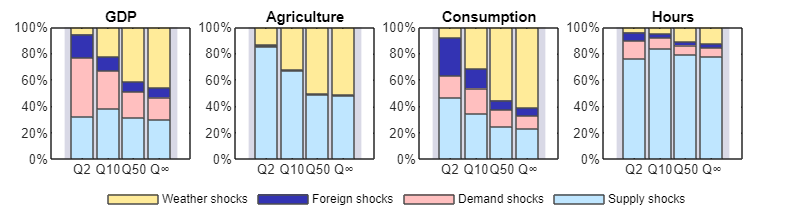

options_.order   = 1;
options_.irf     = 0;
options_.noprint = 1;
options_.conditional_variance_decomposition=[2,10,50,10000];
var_list_        = {'y_obs','y_a_obs','c_obs','h_obs'};
[info, oo_, options_, M_] = stoch_simul(M_, options_, oo_, var_list_);

% --- Data: oo_.conditional_variance_decomposition is [4 x 4 x 4]
% dims = variables x horizons x shock_groups
D = oo_.conditional_variance_decomposition;

% stack into subgroups
vgroup{1} = [ find(strcmp(M_.exo_names,'eta_s'))];
vgroup{2} = [ find(strcmp(M_.exo_names,'eta_c')) find(strcmp(M_.exo_names,'eta_e'))];
vgroup{3} = [ find(strcmp(M_.exo_names,'eta_g')) find(strcmp(M_.exo_names,'eta_i'))];
vgroup{4} = [ find(strcmp(M_.exo_names,'eta_z')) find(strcmp(M_.exo_names,'eta_h')) find(strcmp(M_.exo_names,'eta_n'))];
    
D = zeros([size(oo_.conditional_variance_decomposition,1) size(oo_.conditional_variance_decomposition,2) size(vgroup,2)]);
for ix=1:size(vgroup,2)
     D(:,:,ix) = sum(oo_.conditional_variance_decomposition(:,:,vgroup{ix}),3);
end

var_names = {'GDP','Agriculture','Consumption','Hours'};
h_labels  = {'Q2','Q10','Q50','Q∞'}; % horizon labels
    
% Colors (approximate your palette)
C4 = [0.75 0.90 1.00];  % light blue (bottom)
C3 = [1.00 0.75 0.75];  % light red
C2 = [0.20 0.20 0.70];  % dark blue
C1 = [1.00 0.92 0.60];  % light yellow (top)
cols = [C1; C2; C3; C4];

figure('name','Figure 7: Forecast error variance decomposition at the posterior mean', 'Color','w','Position',[100 100 1100 300]);
tiledlayout(1,4,'Padding','compact','TileSpacing','compact');

for v = 1:4
        nexttile;
    
        % H x G matrix for this variable
        M = squeeze(D(v,:,:));                 % [4 horizons x 4 groups]
        % Normalize each horizon to percentage
        M = 100 * (M ./ sum(M,2));
    
        % Stacked bars (categories=horizons, stacks=groups)
        hb = bar(M,'stacked','BarWidth',0.85);
        for g = 1:4
            hb(g).FaceColor = cols(g,:);
            hb(g).EdgeColor = [0.3 0.3 0.3];
            hb(g).LineWidth = 0.5;
        end
    
        % Axes formatting
        title(var_names{v});
        set(gca,'XTick',1:4,'XTickLabel',h_labels);
        ylim([0 100]);
        yt = 0:20:100;
        yticklabels(strcat(string(yt),"%"));
        box on;
    
        % Optional: light separators to mimic the gaps
        hold on;
        for k = 0.5:1:4.5
            plot([k k],[0 100],'Color',[0.85 0.85 0.90],'LineWidth',6);
        end
        uistack(hb,'top'); % keep bars above separators
end
lg = legend(hb, {'Weather shocks','Foreign shocks','Demand shocks','Supply shocks'}, ...
    'Orientation','horizontal', ...
    'Box','off', ...
    'Location','southoutside');
lg.Layout.Tile = 'south'; % place it under all subplots if using tiledlayout

## Figure 8: The role of weather shocks on selected variables

This section reproduces Figure 8 which isolates the contribution of weather shocks to macroeconomic fluctuations over the historical sample.

The script first extracts the smoothed exogenous shocks estimated by Dynare from the Bayesian estimation results. Using these shocks, the model is solved and simulated to generate the full historical series of key macro variables.

A counterfactual scenario is then computed by re-running the simulation with only the weather shock (ηˢₜ) active, while all other shocks are set to zero.

The resulting figure compares actual simulated dynamics (“All shocks”) with those driven solely by weather shocks (“Weather only”) for selected growth variables: agricultural output, total output, consumption, and hours. This highlights the relative contribution of short-run climatic fluctuations to macroeconomic variability.

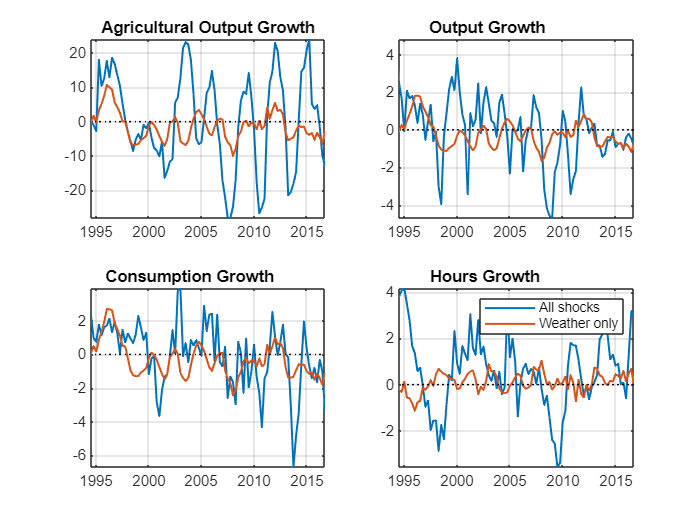

ee=[];

for i1 = 1:M_.exo_nbr
	ee = [ee eval(['oo_.SmoothedShocks.' M_.exo_names{i1}])];
end
% standard model
oo = oo_; 
M  = M_;
[oo.dr,~,M.params] = resol(0, M, options_, oo.dr, oo.dr.ys, oo.exo_steady_state, oo.exo_det_steady_state);
y1 = simult_(M_,options_,oo.dr.ys,oo.dr,ee,1)';
% only weather
idx 		= strmatch('eta_s',M_.exo_names,'exact');
ee2 		= ee*0;
ee2(:,idx)	= ee(:,idx);
% y2			= simult_(oo.dr.ys,oo.dr,ee2,1)';
y2 = simult_(M_,options_,oo.dr.ys,oo.dr,ee2,1)';
% plot the result
yvar   = char('dyA','dy','dc','dH');
ytitle = char('Agricultural Output Growth','Output Growth','Consumption Growth','Hours Growth');
T=1987.25:.25:2016.75;
figure('NumberTitle', 'off', 'Name', 'Figure 8: The role of weather shocks on selected variables');
for i1 = 1:size(yvar,1)
	subplot(2,2,i1)
	idx = strmatch(yvar(i1,:),M_.endo_names,'exact');
	plot(T,y1(2:end,idx),'linewidth',1.2)
	hold on;	
		plot(T,y2(2:end,idx),'linewidth',1.2)
		plot(T,zeros(size(T)),'k:')
		xlim([T(30) T(end)])
		ylim([min(y1(30:end,idx)) max(y1(30:end,idx))])
	hold off;
	title(ytitle(i1,:))
grid;
end
legend('All shocks','Weather only')

## Figure 10: Impulse response functions for different values of the land expenditure cost ψ

This section explores the nonlinear propagation of weather shocks across different values of the parameter ψ.

The exercise introduces a one-standard-deviation innovation to the weather shock (ηˢₜ) and compares impulse responses across alternative values of ψ, which governs the curvature of agents’ preferences or the elasticity of substitution between sectors.

Using the custom function climate_IRF, the model is simulated under three ψ values — baseline, 1.57, and 3.57 — to quantify how climate sensitivity alters the dynamic adjustment of key variables.

M_.params=params;
ids = strmatch('eta_s',M_.exo_names,'exact');
ee = zeros(100,M_.exo_nbr);
ee(5,ids) = 1;
yvar = char('gdp','y_N','y_A','p_N','p_A','land','x','varrho');
climate_IRF('psi',[psi 1.57 3.57],ee,yvar,1,M_,oo_,options_)


## Figure 11: Impulse response functions for various degrees of labor substitution

This section analyzes the impact of cross-sector labor substitution on the transmission of weather shocks.

The parameter ι (iota) controls the elasticity of substitution between agricultural and non-agricultural labor. By varying ι between its baseline value, 0, and 5, the simulation evaluates how labor mobility shapes the short-run adjustment of wages, prices, and output across sectors.

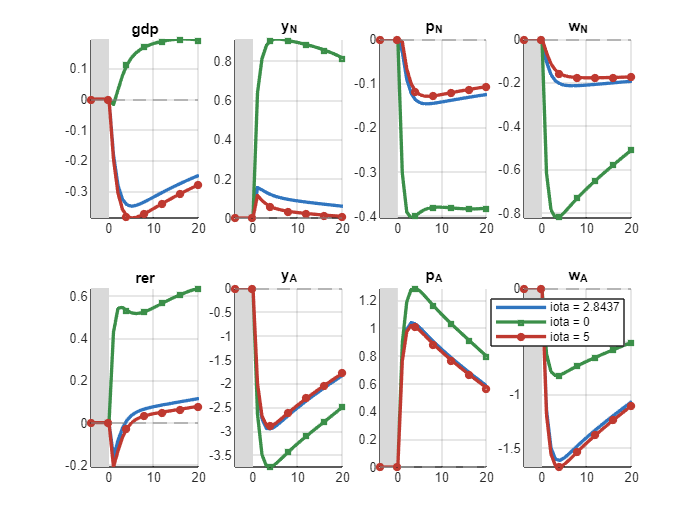

yvar = char('gdp','y_N','p_N','w_N','rer','y_A','p_A','w_A');

climate_IRF('iota',[iota 0 5],ee,yvar,1,M_,oo_,options_)

## Figure 12: Impulse response functions for various decay rates of land efficiency

This section examines how the persistence of land productivity affects the propagation of weather shocks.

The parameter δᴸ (delta_L) governs the adjustment speed or persistence of land productivity following climatic disturbances. By varying δᴸ between its baseline value, 0.01, and 0.1, the model quantifies how slower or faster recovery of land conditions modifies macroeconomic responses to weather shocks (ηˢₜ).

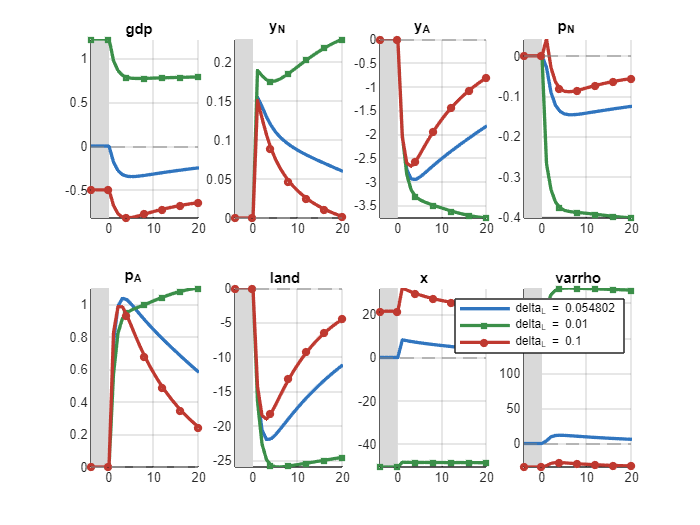

yvar = char('gdp','y_N','y_A','p_N','p_A','land','x','varrho');

climate_IRF('delta_L',[delta_L 0.01 0.1],ee,yvar,1,M_,oo_,options_)


### Table 3: Changes in variances of simulated observables under climate change scenarios.

This section quantifies welfare changes and macroeconomic variability under alternative climate change scenarios.

The experiment compares the baseline model with and without weather shocks and then evaluates future Representative Concentration Pathway (RCP) scenarios by scaling the volatility of weather shocks (σₛ) according to RCP 2.5, 4.5, 6.0, and 8.5.

For each scenario, the model is simulated using Dynare’s stoch_simul command to compute the variances of key macroeconomic observables (output, consumption, investment, prices, interest rate, and external balance). Changes in volatility are reported relative to the historical baseline.

Finally, welfare levels and welfare-equivalent consumption losses are derived to quantify the cost of higher weather variability. The output table reports variance changes across RCP scenarios, welfare indices (W1–W8), and the associated welfare cost in percentage of steady-state consumption.

warning('off')

-------------------------------------------------------


TABLE 7


Changes in variances of simulated observables under climate change scenarios


          	   Hist 	   RCP2 	   RCP4 	   RCP6 	   RCP8 


 eta_W    	   100.00 	   91.97 	   114.11 	   119.44 	   151.91 


   y_obs  	   100.00 	   97.10 	   105.09 	   107.02 	   118.73 
   c_obs  	   100.00 	   95.91 	   107.19 	   109.90 	   126.44 
   i_obs  	   100.00 	   99.27 	   101.29 	   101.77 	   104.74 
 y_a_obs  	   100.00 	   96.70 	   105.80 	   107.99 	   121.33 
     p_A  	   100.00 	   97.48 	   104.43 	   106.11 	   116.32 
   h_obs  	   100.00 	   99.30 	   101.23 	   101.70 	   104.54 
       r  	   100.00 	   99.99 	   100.01 	   100.02 	   100.04 
     rer  	   100.00 	   98.88 	   101.97 	   102.71 	   107.24 
      tb  	   100.00 	   98.29 	   103.01 	   104.15 	   111.08 
     NFA  	   100.00 	   95.40 	   108.08 	   111.14 	   129.73 


 Welfare  	 -634.5185 	 -634.4888 	 -634.5707 	 -634.5905 	 -634.7107 


 Wcost    	   0.2905 	   0.2671 	   0.3315 	   0.3470 	   0.4415 


The (positive) cost: 0.29046


options_.nograph = 1;
options_.noprint = 1;
M_.params = params;
the_sig_s = params(strmatch('sig_s',M_.param_names,'exact'));	
% WELFARE B: WITH WEATHER
var_list_ = {'c','hu','smdi_obs','wy_obs','y_obs','h_obs','y_a_obs','i_obs','c_obs','rer_obs','y','r','land','p_A','p_N','rer','tb','NFA','gdp','i','y_A','h'};
% info = stoch_simul(var_list_);
[info, oo_, options_, M_] = stoch_simul(M_, options_, oo_, var_list_);
sd_b = diag(oo_.var);
cov_b = oo_.var;
% WELFARE A : NO WEATHER
set_param_value('sig_s',0);
% info = stoch_simul(var_list_);
[info, oo_, options_, M_] = stoch_simul(M_, options_, oo_, var_list_);
sd_a = diag(oo_.var);
cov_a = oo_.var;
	
%% HISTORICAL SCENARIO
M_.params=params;
set_param_value('sig_s',the_sig_s);
% info = stoch_simul(var_list_);
[info, oo_, options_, M_] = stoch_simul(M_, options_, oo_, var_list_);
sd_rcp0 = diag(oo_.var);
sigss_s = [sig_s^2];
cov_rcp0 = oo_.var;
%% RCP 2.5 SCENARIO
set_param_value('sig_s',the_sig_s*.9590);
% info = stoch_simul(var_list_);
[info, oo_, options_, M_] = stoch_simul(M_, options_, oo_, var_list_);
sd_rcp2 = diag(oo_.var);
sigss_s = [sigss_s sig_s^2];
cov_rcp2 = oo_.var;
%% RCP 4.5
set_param_value('sig_s',the_sig_s*1.0682);
% info = stoch_simul(var_list_);
[info, oo_, options_, M_] = stoch_simul(M_, options_, oo_, var_list_);
sd_rcp4 = diag(oo_.var);
sigss_s = [sigss_s sig_s^2];
cov_rcp4 = oo_.var;
%% RCP 6
set_param_value('sig_s',the_sig_s*1.0929);
% info = stoch_simul(var_list_);
[info, oo_, options_, M_] = stoch_simul(M_, options_, oo_, var_list_);
sd_rcp6 = diag(oo_.var);
sigss_s = [sigss_s sig_s^2];
cov_rcp6 = oo_.var;
%% RCP 8.5
set_param_value('sig_s',the_sig_s*1.2325);
% info = stoch_simul(var_list_);
[info, oo_, options_, M_] = stoch_simul(M_, options_, oo_, var_list_);
sd_rcp8 = diag(oo_.var);
sigss_s = [sigss_s sig_s^2];
cov_rcp8 = oo_.var;
	
id_c = strmatch('c',var_list_,'exact');
id_hu = strmatch('hu',var_list_,'exact');
	 
disp('-------------------------------------------------------')
chi_ss = M_.params(strmatch('chi',M_.param_names,'exact'));
C_ss   = oo_.dr.ys(strmatch('c',M_.endo_names,'exact'));
H_ss   = oo_.dr.ys(strmatch('hu',M_.endo_names,'exact'));
v_c_b  = sd_b(1);
v_c_a  = sd_a(1);
v_h_b  = sd_b(2);
v_h_a  = sd_a(2);
	
	
Uc		= 1/(1-sigmaC)*(C_ss-b*C_ss)^(1-sigmaC);
gamma_H = 1/2*sigmaH*chi_ss*H_ss^(sigmaH-1);
gamma_C = 1/2*(sigmaC*(1-b^2)*(C_ss-b*C_ss)^(-sigmaC-1));
L1 = (Uc-gamma_C*v_c_a+gamma_H*(v_h_b-v_h_a)) / ( Uc-gamma_C*v_c_b);
L2 = (Uc-gamma_C*v_c_a+gamma_H*(sd_rcp2(id_hu)-v_h_a)) / ( Uc-gamma_C*sd_rcp2(id_c));
L4 = (Uc-gamma_C*v_c_a+gamma_H*(sd_rcp4(id_hu)-v_h_a)) / ( Uc-gamma_C*sd_rcp4(id_c));
L6 = (Uc-gamma_C*v_c_a+gamma_H*(sd_rcp6(id_hu)-v_h_a)) / ( Uc-gamma_C*sd_rcp6(id_c));
L8 = (Uc-gamma_C*v_c_a+gamma_H*(sd_rcp8(id_hu)-v_h_a)) / ( Uc-gamma_C*sd_rcp8(id_c));
u_ss = Uc - 1/(1+sigmaH)*chi_ss*H_ss^(1+sigmaH);
W1 = u_ss/(1-beta) - 1/2*sigmaC*(1-b^2)*(C_ss-b*C_ss)^(-sigmaC-1)/(1-beta)*sd_rcp0(id_c) - 1/2*sigmaH*chi_ss*H_ss^(sigmaH-1)/(1-beta)*sd_rcp0(id_hu);
W2 = u_ss/(1-beta) - 1/2*sigmaC*(1-b^2)*(C_ss-b*C_ss)^(-sigmaC-1)/(1-beta)*sd_rcp2(id_c) - 1/2*sigmaH*chi_ss*H_ss^(sigmaH-1)/(1-beta)*sd_rcp2(id_hu);
W4 = u_ss/(1-beta) - 1/2*sigmaC*(1-b^2)*(C_ss-b*C_ss)^(-sigmaC-1)/(1-beta)*sd_rcp4(id_c) - 1/2*sigmaH*chi_ss*H_ss^(sigmaH-1)/(1-beta)*sd_rcp4(id_hu);
W6 = u_ss/(1-beta) - 1/2*sigmaC*(1-b^2)*(C_ss-b*C_ss)^(-sigmaC-1)/(1-beta)*sd_rcp6(id_c) - 1/2*sigmaH*chi_ss*H_ss^(sigmaH-1)/(1-beta)*sd_rcp6(id_hu);
W8 = u_ss/(1-beta) - 1/2*sigmaC*(1-b^2)*(C_ss-b*C_ss)^(-sigmaC-1)/(1-beta)*sd_rcp8(id_c) - 1/2*sigmaH*chi_ss*H_ss^(sigmaH-1)/(1-beta)*sd_rcp8(id_hu);


varnames = {'y_obs', 'c_obs', 'i_obs', 'y_a_obs', 'p_A', 'h_obs', 'r', 'rer', 'tb', 'NFA'};
disp('TABLE 7')
disp('Changes in variances of simulated observables under climate change scenarios')
fprintf('%8s  \t   %4s \t   %4s \t   %4s \t   %4s \t   %4s \n',' ','Hist','RCP2','RCP4','RCP6','RCP8')
fprintf('%8s  \t   %2.2f \t   %2.2f \t   %2.2f \t   %2.2f \t   %2.2f \n','eta_W  ',100*(sigss_s(1)/sigss_s(1)),100*(sigss_s(2)/sigss_s(1)),100*(sigss_s(3)/sigss_s(1)),100*(sigss_s(4)/sigss_s(1)),100*(sigss_s(5)/sigss_s(1)));
for i1 = 1:size(varnames,2)
	idx = strmatch(deblank(varnames{i1}),var_list_,'exact');
	if isempty(idx)
		warning(['Error: ' varnames{i1}])
	end
	fprintf('%8s  \t   %2.2f \t   %2.2f \t   %2.2f \t   %2.2f \t   %2.2f \n',...
			varnames{i1},100*sd_rcp0(idx)/sd_rcp0(idx),100*sd_rcp2(idx)/sd_rcp0(idx),100*sd_rcp4(idx)/sd_rcp0(idx),100*sd_rcp6(idx)/sd_rcp0(idx),100*sd_rcp8(idx)/sd_rcp0(idx));
end
fprintf('%8s  \t %4.4f \t %4.4f \t %4.4f \t %4.4f \t %4.4f \n','Welfare',W1,W2,W4,W6,W8);
fprintf('%8s  \t   %4.4f \t   %4.4f \t   %4.4f \t   %4.4f \t   %4.4f \n','Wcost  ',100*(L1^(1/(1-sigmaC))-1),100*(L2^(1/(1-sigmaC))-1),100*(L4^(1/(1-sigmaC))-1),100*(L6^(1/(1-sigmaC))-1),100*(L8^(1/(1-sigmaC))-1));


disp(['The (positive) cost: ' num2str(100*(L1^(1/(1-sigmaC))-1)) ])

## Table 3: Model comparison

dynare COMPARE